# Interactive manuscript

Welcome to this MATLAB Live Script which brings to life the figures in Walker et al. (2020) and enables you to interact with the wealth of data published with this article - 216 sperm flagellar waveforms are at your fingertips! 

**Reference**: Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms of bovine spermatozoa. *R. Soc. Open Sci*. **7**: 200769

**User instructions**: You must run this script from the parent folder, i.e. the main directory where you have downloaded our GitHub repository. In other words, your Current Folder in MATLAB should be '...\CambridgeFertiliTEAM_DataChallenge2_SolutionTitle'. This live script was tested on both Windows and Mac machines running MATLAB R2023a or above with Curve Fitting Toolbox.

**GUI experience**: To hide all code and immerse yourself in the science, select Hide Code from the vertical ribbon to the right of the scroll bar. 

% NOTE: This MATLAB live script contains a mixture of code written by
% -- the authors of Walker BJ, Phuyal S, Ishimoto K, Tung C-K, Gaffney EA. 
% (2020) Computer-assisted beat-pattern analysis and the flagellar waveforms 
% of bovine spermatozoa. R. Soc. Open Sci. 7: 200769
% (particularly for reproducing Fig. 1)
% -- the members of Cambridge FertiliTEAM for inFer GW4 network Hackathon
clear; clc; close all; 

## Large-scale quantification of flagellar beating - Fig. 1

Let's start by reproducing and exploring Fig. 1. Click 'Get started' below to load the data and functions necessary for other sections to run. 

*Note: There may be some waiting time if you are loading the data for the first time.*

 

% add folders to path so can e.g. run functions in those folders
addpath('Data',  'Functions',  'Images',  'Movies')

% load data for plotting waveforms of all 216 sperm
% This function call is a bit slow; don't run unless necessary
if ~exist('data', 'var') % check if data exists 
    data = load_all_data();
end

% load data for figure with real beat; assign beat data to new variable to
% avoid variable name conflict
load('Data/real.mat','beat')
realBeat = beat;

% load data for figure with synthetic beat; assign beat data to new variable
load('Data/synthetic.mat','beat')
syntheticBeat = beat;

% colours for real and synthetic beat figures
cc = importdata('Data/colormap.txt');
inds = 1 : 4 : 100;
cc = cc(inds,:);

% find min and max of all y values in waveform, for purpose of ylim for
% plots
allValues = [];
for i=1:216
    allValues = [allValues; data{i}.cartesian(:,:,2)];
end
waveformMiny = min(allValues,[],"all");
waveformMaxy = max(allValues,[],"all");

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Figure aesthetics
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Color scheme
red = [1,0,0];
lightred = [1,1,1]-0.3*[0,1,1];
blue = [0,0,1];
lightblue = [1,1,1]-0.3*[1,1,0];
% Font sizes
title_FontSize = 14;
axlabels_FontSize = 12;
legend_FontSize = 12;

### Image of swimming bovine spermatozoa - Fig. 1(a)

Here is a sample captured frame from a video of a fresh spermatozoon swimming in Tyrode Albumin Lactate Pyruvate (TALP), a standard medium for bovine sperm.

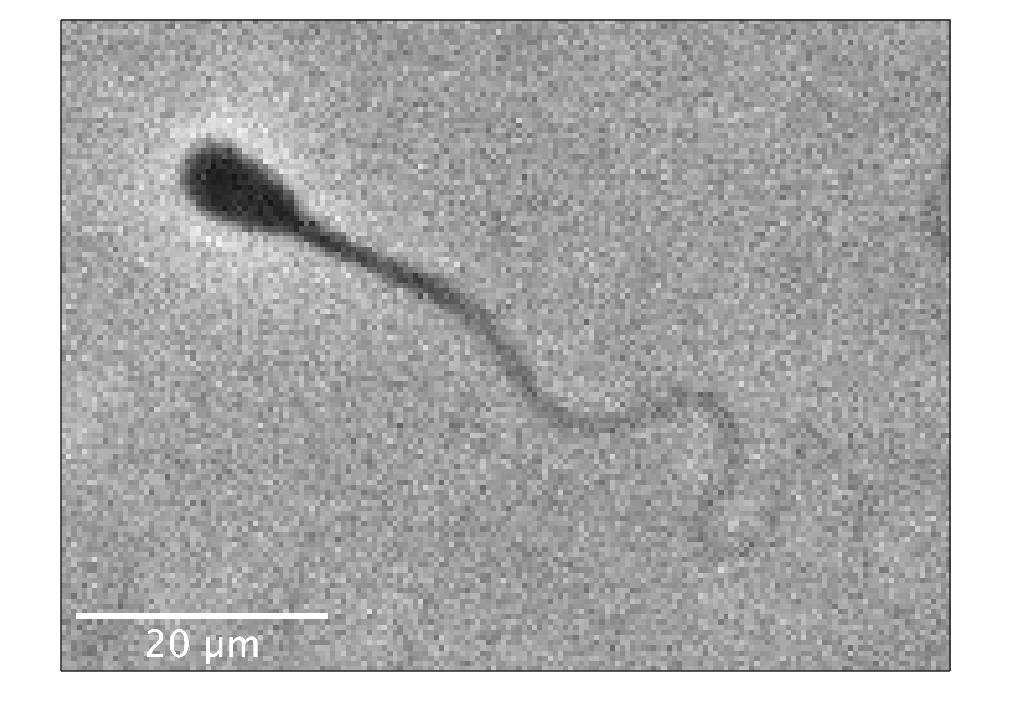

 
figure
imshow( imread('Data/raw.tif') ,[0 255]);
axis on
set(gca,'XTick',[],'YTick',[])
box on

### Automated tracing of the flagellum - Fig. 1(b)

The next step is to trace the flagellum. Walker et al. (2020) use an automated methodology developed in one of their previous studies. Click 'View' to see the traced flagellum for to the sample frame shown above.

**Reference**: Walker BJ, Ishimoto K, Wheeler RJ. 2019 Automated identification of flagella from videomicroscopy via the medial axis transform. Sci. Rep. 9, 5015. (doi:10.1038/s41598-019-41459-9).

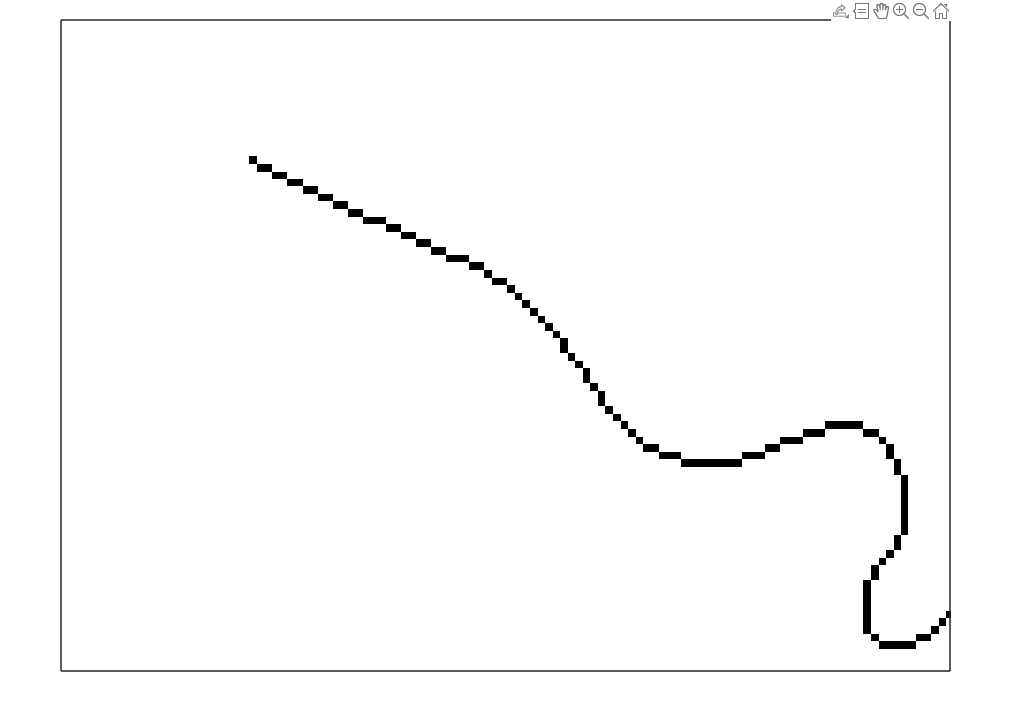

 
figure
imshow( imread('Data/flag.tif') ,[0 255]);
axis on
set(gca,'XTick',[],'YTick',[])
box on

### Animated real flagellar waveform - Fig. 1(c)

By tracing the flagellum in each video frame, it is possible to reconstruct the waveform over an entire beating period. 

**Click 'Watch' below to make Fig. 1(c) come to life!** The captured waveform (thick black line) is shown against an envelope of light grey lines depicting the waveform at all timepoints within a beating period.

*Note: There will be some waiting time while MATLAB plots the figure for the first time, after which you can click the Play button underneath the animation to watch the beating waveform in real time. *

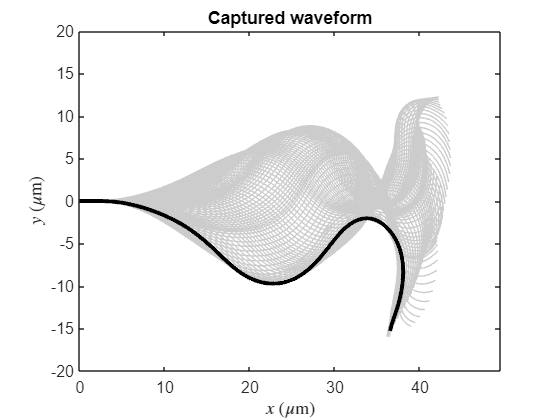

 

figure
for timepoint=1:100
    clf
    % plot in grey the waveform at all timepoints
    plot(realBeat.xy(:,:,1)',realBeat.xy(:,:,2)','color','#cccccc')
    hold on
    % plot the waveform at the current timepoint
    plot(realBeat.xy(timepoint,:,1)',realBeat.xy(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    set(gca,'FontSize',axlabels_FontSize)
    xlims = [0,49.457];
    ylims = [-20,20];
    xlim(xlims)
    ylim(ylims)
    set(gca,'XTick',[0 10 20 30 40])
    title('Captured waveform','FontSize',title_FontSize)
    drawnow
end

### Beyond the manuscript

You can explore the dataset provided by Walker et al. (2020) in more detail with our Live Script **explore_waveforms.mlx**. Additional features of this live script:

- watch the beating waveform of all 216 sperm 

- compare the waveforms of two (or more!) sperm side by side

### Animated synthetic flagellar waveform - Fig. 1(d)

An exciting application of the data provided by Walker et al. (2020) is the possibility to generate synthetic flagellar waveforms. These are new computer-generated waveforms that have not been directly observed with video microscopy, but are consistent with their dataset of over 200 sperm bovine waveforms. The similarity is based on a quantitative analysis using the method of principal component analysis (PCA), which will be described in more detail below.

**Click 'Watch' below to make Fig. 1(d) come to life!** The synthesised waveform (thick black line) is shown against an envelope of light grey lines depicting the waveform at all timepoints within a beating period.

*Note: There will be some waiting time while MATLAB plots the figure for the first time, after which you can click the Play button underneath the animation to watch the beating waveform in real time. *

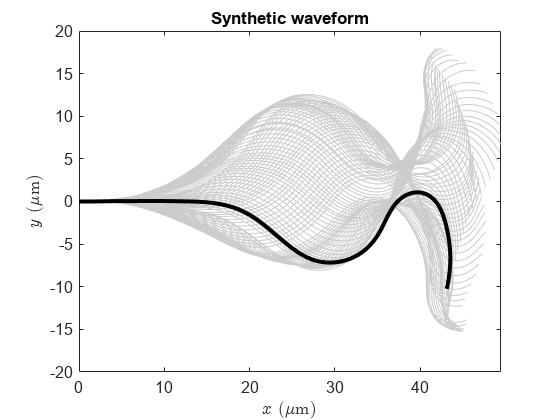


 

figure
for timepoint=1:100
    clf
    % plot in grey the waveform at all timepoints
    plot(syntheticBeat.xy(:,:,1)',syntheticBeat.xy(:,:,2)','color','#cccccc')
    hold on
    % plot the current waveform
    plot(syntheticBeat.xy(timepoint,:,1)',syntheticBeat.xy(timepoint,:,2)','color','k','LineWidth',3)
    axis equal
    xlabel('$x$ ($\mu$m)','interpreter','latex')
    ylabel('$y$ ($\mu$m)','interpreter','latex')
    set(gca,'FontSize',axlabels_FontSize)
    xlims = [0,49.457];
    ylims = [-20,20];
    xlim(xlims)
    ylim(ylims)
    set(gca,'XTick',[0 10 20 30 40])
    title('Synthetic waveform','FontSize',title_FontSize)
    drawnow
end

### Beyond the manuscript

You can explore the dataset provided by Walker et al. (2020) in more detail with our Live Script **explore_waveforms.mlx**. Additional features of this live script:

- generate and watch a brand new synthetic waveform - there is no limit to what a (synthetic) sperm can do! 

## Quantitative analysis of waveforms - Fig. 2

Having extracted the waveforms of over 200 bovine sperm, Walker et al. (2020) proceed by distilling this wealth of information into a set of 'modes' or principal components using the method of principal component analysis (PCA). Let's load the available PCA data!

 
% load data for PCA figures
load('Data/pop_pca.mat','modes','coeff','A_mask','B_mask')

num_frames = 100; % timepoints
total_num = 216;  % number of swimmers

% Prepare coeff array for histogram plotting
% reshape coeff (2 dimensions) into cell_coeff (3 dimensions)
cell_coeff = zeros(num_frames,total_num,size(modes,2));
for i = 1 : total_num
	cell_coeff(:,i,:) = coeff((i-1)*num_frames+1:i*num_frames,:);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Analyse PCA data
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Limits (min/max coeff values) for binning data into histograms
lim = 0.72;
min_c1 = -lim*1.1;
max_c1 = lim*1.1;
num_bins = 30;
bins = linspace(min_c1,max_c1,num_bins+1);
mid_bins = (bins(1:end-1) + bins(2:end))/2;
to_plot_A = zeros(num_frames,num_bins);
to_plot_B = zeros(num_frames,num_bins);
to_plot_all = zeros(num_frames,num_bins);
hist_plot_A = zeros(num_frames,num_bins);
hist_plot_B = zeros(num_frames,num_bins);
hist_plot_all = zeros(num_frames,num_bins);
for i = 1 : num_frames
	to_plot_A(i,:) = histcounts(cell_coeff(i,A_mask,1),bins,'normalization','pdf');
	to_plot_B(i,:) = histcounts(cell_coeff(i,B_mask,1),bins,'normalization','pdf');
    to_plot_all(i,:) = histcounts(cell_coeff(i,:,1),bins,'normalization','pdf');
    hist_plot_A(i,:) = histcounts(cell_coeff(i,A_mask,1),bins,'Normalization','probability');
    hist_plot_B(i,:) = histcounts(cell_coeff(i,B_mask,1),bins,'Normalization','probability');
    hist_plot_all(i,:) = histcounts(cell_coeff(i,:,1),bins,'Normalization','probability');
end

### Beyond the manuscript

You can explore the method of principal component analysis in more detail with our Live Script **explore_waveforms.mlx**. Additional features of this live script:

- try to manually reconstruct the waveform using the first three modes - how well can your eyes match the computer-generated best fit?

- compare the reconstructed waveforms with a variable number of modes (from 1 to 20)

### Waveform variation across spermatozoa - Fig. 2(a,b)

We are now ready to see how the first principal component varies over time and across spermatozoa. Use the filters below to select which sample you want to plot, and which variable you want to focus on. 

Sample A - fresh sperm (1-79)

Sample B - thawed sperm (80-216)

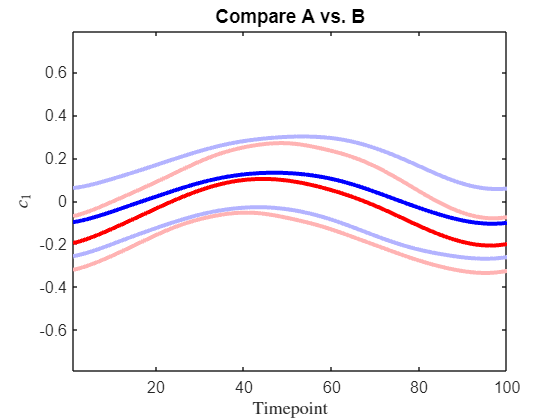

sample ='compare'; 
alldataon = true; 
averageon = true; 
upboundon = true; 
loboundon = true;

 

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Apply filters
%%%%%%%%%%%%%%%%%%%%%%%%%%%
switch true
    case strcmp(sample, 'A')
        mymask = A_mask;
        mytitle = 'Sample A';
    case strcmp(sample, 'B')
        mymask = B_mask;
        mytitle = 'Sample B';
    case strcmp(sample, 'compare')
        alldataon = false;
        mytitle = 'Compare A (red) vs. B (blue)';
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot first principal mode coefficient against time
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
hold on
switch true
    case strcmp(sample, 'compare')
        if alldataon; plot(cell_coeff(:,A_mask,1),'Color',0.8*[1,1,1]); end
        if averageon; plot(mean(cell_coeff(:,A_mask,1),2),'LineWidth',3,'Color',red); end
        if upboundon; plot(mean(cell_coeff(:,A_mask,1),2)+std(cell_coeff(:,A_mask,1),0,2),'LineWidth',3,'Color',lightred); end
        if loboundon; plot(mean(cell_coeff(:,A_mask,1),2)-std(cell_coeff(:,A_mask,1),0,2),'LineWidth',3,'Color',lightred); end
                
        if alldataon; plot(cell_coeff(:,B_mask,1),'Color',0.8*[1,1,1]); end
        if averageon; plot(mean(cell_coeff(:,B_mask,1),2),'LineWidth',3,'Color',blue); end
        if upboundon; plot(mean(cell_coeff(:,B_mask,1),2)+std(cell_coeff(:,B_mask,1),0,2),'LineWidth',3,'Color',lightblue); end
        if loboundon; plot(mean(cell_coeff(:,B_mask,1),2)-std(cell_coeff(:,B_mask,1),0,2),'LineWidth',3,'Color',lightblue); end
    otherwise 
        if alldataon; plot(cell_coeff(:,mymask,1),'Color',0.8*[1,1,1]); end
        if averageon; plot(mean(cell_coeff(:,mymask,1),2),'LineWidth',3,'Color','black'); end
        if upboundon; plot(mean(cell_coeff(:,mymask,1),2)+std(cell_coeff(:,mymask,1),0,2),'LineWidth',3,'Color',0.4*[1,1,1]); end
        if loboundon; plot(mean(cell_coeff(:,mymask,1),2)-std(cell_coeff(:,mymask,1),0,2),'LineWidth',3,'Color',0.4*[1,1,1]); end
end
set(gca,'FontSize',axlabels_FontSize)
axis([1 100 min_c1 max_c1])
xlabel('Timepoint','interpreter','latex')
ylabel('$c_1$','interpreter','latex')
box on
title(mytitle,'FontSize',title_FontSize)

### Waveform variation across spermatozoa - Fig. 2(c,d)

An alternative way to visualize the variation of the first principal component across the sample is via histograms. 

**Left**: This histogram shows you the frequency of the coefficient c1 across the chosen sample (A, B, or both) at a specific moment in time (select timepoint with numeric slider). 

**Right**: By sweeping through the entire time series, it is possible to see all the data at once as a pseudocolor plot where each vertical column represents the histogram at a moment in time, and the colour at each pixel represents to the height of the corresponding bin in the histogram. The colour of the bins corresponds to the colour of the timepoint indicated on the left.

Use the filters below to select which sample you want to plot, and which timepoints you want to focus on.

Sample A - fresh sperm (1-79)

Sample B - thawed sperm (80-216)

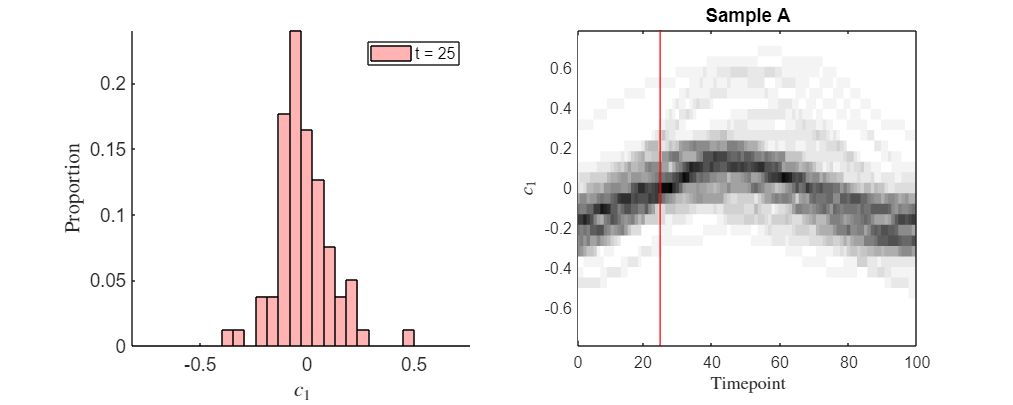

sample ='A'; 
timepoint1 = 25;
 t2on = false; timepoint2 = 70;

 

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Apply filters
%%%%%%%%%%%%%%%%%%%%%%%%%%%
switch true
    case strcmp(sample, 'A')
        to_plot = to_plot_A;
        hist_plot = hist_plot_A;
        mytitle = 'Sample A';
    case strcmp(sample, 'B')
        to_plot = to_plot_B;
        hist_plot = hist_plot_B;
        mytitle = 'Sample B';
    case strcmp(sample, 'both')
        to_plot = to_plot_all;
        hist_plot = hist_plot_all;
        mytitle = 'Samples A & B';
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot histograms of first principal mode coefficients
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fig = figure;
fig.Position(3:4) = [1250 500];

% Standard histogram for selected timepoints only
subplot(1,2,1)
hold on; 
mybarwidth = 1;
if t2on
    b = bar(bins(1:end-1),[hist_plot(timepoint1,:); hist_plot(timepoint2,:)]','BarWidth',mybarwidth);
    b(1).FaceColor = lightred;
    b(2).FaceColor = lightblue;
    legend([b(2),b(1)],{['t = ' num2str(timepoint1)],['t = ' num2str(timepoint2)]},'FontSize',legend_FontSize)
else
    b = bar(bins(1:end-1),hist_plot(timepoint1,:)','BarWidth',mybarwidth);
    b.FaceColor = lightred;
    legend(b(1),{['t = ' num2str(timepoint1)]},'FontSize',legend_FontSize)
end
xlabel('$c_1$','interpreter','latex')
ylabel('Proportion','interpreter','latex')
set(gca,'FontSize',title_FontSize)
axis tight

% Pseudocolor plot of histograms at all timepoints
subplot(1,2,2)
hold on
h = pcolor((1:num_frames) -0.5 ,mid_bins,to_plot');
set(h, 'EdgeColor', 'none');
axis([1 100 min_c1 max_c1])
% Indicate selected timepoints with vertical color lines
if t2on; plot(timepoint2*[1,1],[min_c1 max_c1],'-','Color',blue,'LineWidth',1); end
plot(timepoint1*[1,1],[min_c1 max_c1],'-','Color',red,'LineWidth',1)
xlabel('Timepoint','interpreter','latex')
ylabel('$c_1$','interpreter','latex')
box on
set(gca,'FontSize',axlabels_FontSize,'XTick',[1,20,40,60,80,100],'XTickLabel',{'0','20','40','60','80','100'})
colormap('gray')
colormap(flipud(colormap))
title(mytitle,'FontSize',title_FontSize)

## Quantitative waveform comparison of samples

You may have noticed from the reproduced Fig. 2(a,b) that the coefficient of the first mode varies sinusoidally over time. Walker et al. (2020) used this feature of the data to make a quantitative comparison between the waveforms of fresh (sample A) vs. thawed (sample B) spermatozoa. The first principle component $c_{1\;}$is decomposed into a constant component $\alpha \;$and and a sinusoidal component $\beta \;$as 

    $c_1 =\alpha \;+\beta \;\cos \left(\textrm{kt}-\phi \;\right)$,

where the wavenumber $k$ and the phase $\phi \;$come from a nonlinear fit to the coefficients of all sperm in the dataset. 

When two samples are compared, the probabiliy that the samples in question are drawn from the same probability distribution (i.e. the p-value of the Kolmogorov-Smirnov test) is also displayed. Dashed lines in histograms indicate median values.

### Interactive comparison between samples - beyond Fig. 3

To delve deeper into the data provided by Walker et al. (2022), our live script gives you the opportunity to compare multiple data subsets, going beyond the comparison between Sample A and Sample B shown in Fig. 3. 

Which sample do you wish to plot?

sample = 3;

To reproduce Figure 3 exactly, select A vs. B. 

 
load('Data/cell_coeffs.mat')
load('Data/masks.mat')
total_num = size(cell_coeff,2);
Const = zeros(total_num,1);
Cosine = zeros(total_num,1);
% The wavenumber and phase come from a nonlinear fit of the mean of all cell_coeff(:,:,1).
ft = fittype( {'1', '(cos(0.8901*x-2.574))'}, 'independent', 'x', 'dependent', 'y', 'coefficients', {'a', 'b'} );
ts = (1:100)' * (2*pi/100);
% Fit model to data.
for i = 1 : total_num
	f = fit(ts, cell_coeff(:,i), ft);
	Const(i) = f.a;
	Cosine(i) = f.b;
end
A_const = Const(A_mask);
B_const = Const(B_mask);
A_cosine = Cosine(A_mask);
B_cosine = Cosine(B_mask);

bleb_const = B_const(find(bleb_mask == 1) - 79);
unbleb_const = B_const(find(unbleb_mask == 1) - 79);
bleb_cosine = B_cosine(find(bleb_mask == 1) - 79);
unbleb_cosine = B_cosine(find(unbleb_mask == 1) - 79);

fig = figure;
fig.Position(3:4) = [1250 500];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Distributions of alpha
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(1,2,1)
hold on

if sample == 3
% Make the figure for A vs B.
A_col = 0.8;
B_col = 0.2;
minx = min([A_const;B_const]);
maxx = max([A_const;B_const]);
edges = linspace(-0.4,0.5,15);
hA = histcounts(A_const,edges,'Normalization','probability');
hB = histcounts(B_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_const),1,2),[0,max([hA,hB])],'--','Color',A_col*0.7*[1,1,1],'LineWidth',2)
plot(repmat(median(B_const),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'Sample A','Sample B'})

% Const
[h,p] = kstest2(A_const,B_const);
disp(['KS p value (const): ' num2str(p)])

elseif sample == 1
A_col = 0.8;
B_col = 0.2;
minx = min(A_const);
maxx = max(A_const);
edges = linspace(-0.4,0.5,15);
hA = histcounts(A_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),(hA)','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_const),1,2),[0,max(hA)],'--','Color',A_col*0.7*[1,1,1],'LineWidth',2)
legend([b(1)],{'Sample A'})

elseif sample == 2
B_col = 0.2;
minx = min(B_const);
maxx = max(B_const);
edges = linspace(-0.4,0.5,15);
hB = histcounts(B_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_const),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(1)],'Sample B')

elseif sample == 6
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_const;unbleb_const]);
maxx = max([bleb_const;unbleb_const]);
edges = linspace(-0.4,0.5,15);
hA = histcounts(bleb_const,edges,'Normalization','probability');
hB = histcounts(unbleb_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_const),1,2),[0,max([hA,hB])],'--','Color',A_col*0.7*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_const),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'blebbed','unblebbed'})


% Const
bleb_const = Const(bleb_mask);
unbleb_const = Const(unbleb_mask);
[h,p] = kstest2(bleb_const,unbleb_const);
disp(['KS p value (const): ' num2str(p)])

elseif sample == 4
A_col = 0.8;
B_col = 0.2;
minx = min(bleb_const);
maxx = max(bleb_const);
edges = linspace(-0.4,0.5,15);
hA = histcounts(bleb_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_const),1,2),[0,max(hA)],'--','Color',A_col*0.7*[1,1,1],'LineWidth',2)
legend([b(1)],{'blebbed'})

elseif sample == 5
B_col = 0.2;
minx = min(unbleb_const);
maxx = max(unbleb_const);
edges = linspace(-0.4,0.5,15);
hB = histcounts(unbleb_const,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_const),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'unblebbed'})

end

KS p value (const): 0.0014016


xlabel('$\alpha$','interpreter', 'latex')
ylabel('Proportion','interpreter', 'latex')
set(gca,'FontSize',axlabels_FontSize)
axis tight

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Distributions of beta
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(1,2,2)
hold on

if sample == 3
A_col = 0.8;
B_col = 0.2;
minx = min([A_cosine;B_cosine]);
maxx = max([A_cosine;B_cosine]);
edges = linspace(-0.1,0.4,15);
hA = histcounts(A_cosine,edges,'Normalization','probability');
hB = histcounts(B_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_cosine),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B_cosine),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'Sample A','Sample B'})

% Cosine

[h,p] = kstest2(A_cosine,B_cosine);

disp(['KS p value (cosine): ',num2str(p)])

disp(' ')

elseif sample == 1
A_col = 0.8;
minx = min(A_cosine);
maxx = max(A_cosine);
edges = linspace(-0.1,0.4,15);
hA = histcounts(A_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_cosine),1,2),[0,max(hA)],'--','Color',A_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'Sample A'})

elseif sample == 2
B_col = 0.2;
minx = min([A_cosine;B_cosine]);
maxx = max([A_cosine;B_cosine]);
edges = linspace(-0.1,0.4,15);
hB = histcounts(B_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_cosine),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'Sample B'})

elseif sample == 6
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_cosine;unbleb_cosine]);
maxx = max([bleb_cosine;unbleb_cosine]);
edges = linspace(-0.1,0.4,15);
hA = histcounts(bleb_cosine,edges,'Normalization','probability');
hB = histcounts(unbleb_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_cosine),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_cosine),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'blebbed','unblebbed'})

% Cosine
bleb_cosine = Cosine(bleb_mask);
unbleb_cosine = Cosine(unbleb_mask);
[h,p] = kstest2(bleb_cosine,unbleb_cosine);

disp(['KS p value (cosine): ',num2str(p)])

elseif sample == 4
A_col = 0.8;
minx = min(bleb_cosine);
maxx = max(bleb_cosine);
edges = linspace(-0.1,0.4,15);
hA = histcounts(bleb_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_cosine),1,2),[0,max(hA)],'--','Color',A_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'blebbed'})

elseif sample == 5
B_col = 0.2;
minx = min([bleb_cosine;unbleb_cosine]);
maxx = max([bleb_cosine;unbleb_cosine]);
edges = linspace(-0.1,0.4,15);
hB = histcounts(unbleb_cosine,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_cosine),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'unblebbed'})
end

KS p value (cosine): 0.0011305


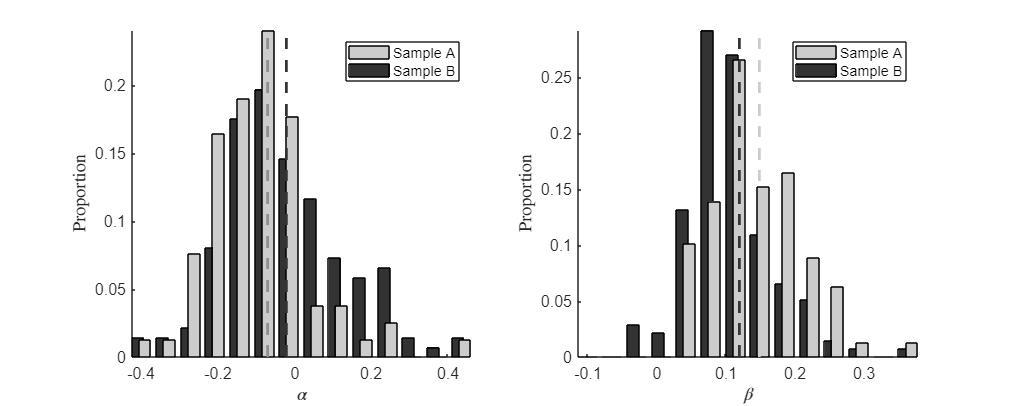

xlabel('$\beta$','interpreter', 'latex')
ylabel('Proportion','interpreter', 'latex')
set(gca,'FontSize',axlabels_FontSize)
axis tight

## Waveform reconstruction

Next, we are going to see how the 'modes' found via principal component analysis (PCA) can be used to reconstruct the flagellar waveform. 

### Animated waveform reconstruction - Fig. 4(a,c,e)

Using only the most prominent Cartesian PCA modes, we will reconstruct the average flagellar waveform from the cumulative contributions of 

- the first mode, 

- the first two modes,  

- the first three modes,

from top to bottom in figure below. You can select the number of beat periods over which you want to watch the reconstructed waveforms beat. Let's make Figure 4 come to life! 

periods_to_run = 2; % for how many time periods do you want to visualize the beat

*Note: There will be some waiting time while MATLAB plots the figure for the first time, after which you can click the Play button underneath the animation to watch the beating waveform in real time. *

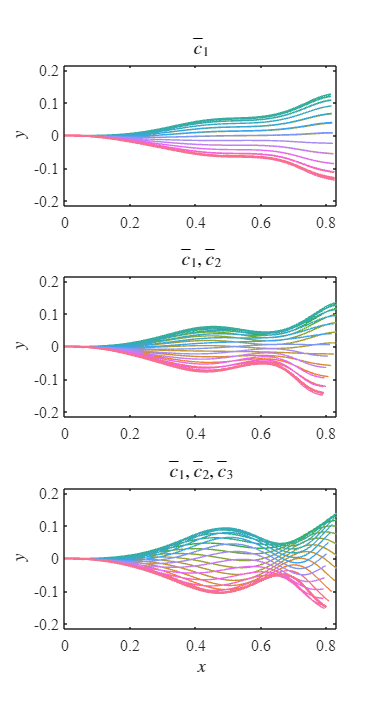

 

if ~exist('coeff_op', 'var')
    load('data_pca_2kModes_vShort.mat', 'coeff_op', 'modes_op', 'mu_op')
end

% colours for reconstructed waveform figures
cc = importdata('Data/colormap.txt');

start_ind = 1;
end_ind   = 100;
ind_skip = 1;

inds = start_ind:ind_skip:end_ind;

cc = cc(inds,:);

cols_r = cc(:,1);
cols_g = cc(:,2);
cols_b = cc(:,3);

coeff_dup = coeff_op(:,1:3); % duplicating the 'coeff' matrix

mu_x = mu_op(1:1000);
mu_y = mu_op(1001:2000);

c1_mat = reshape(coeff_dup(:,1),[100, 216]); c1_bar = mean(c1_mat, 2);
c2_mat = reshape(coeff_dup(:,2),[100, 216]); c2_bar = mean(c2_mat, 2);
c3_mat = reshape(coeff_dup(:,3),[100, 216]); c3_bar = mean(c3_mat, 2);

figure
set(gcf, 'position', [607    66   388   707])

ax1 = subplot(3,1,1);
ax2 = subplot(3,1,2);
ax3 = subplot(3,1,3);

for pp = 1:periods_to_run
    for i = start_ind:ind_skip:end_ind
        plotCol = [cols_r( (i-1)/ind_skip + 1 ), cols_g( (i-1)/ind_skip + 1 ), cols_b( (i-1)/ind_skip + 1 )];
        
        if pp == 1
            if mod(i,4) == 0
                ax1 = subplot(3,1,1);
                h11 = plot( c1_bar(i) * modes_op(1:1000,1) + mu_x', c1_bar(i) * modes_op(1001:2000,1) + mu_y', 'color', plotCol, 'LineWidth', 0.5); hold all
                daspect([1 1 1])

                ax2 = subplot(3,1,2);
                h12 = plot( c1_bar(i) * modes_op(1:1000,1) + c2_bar(i) * modes_op(1:1000,2) + mu_x', ...
                    c1_bar(i) * modes_op(1001:2000,1) + c2_bar(i) * modes_op(1001:2000,2) + mu_y', 'color', plotCol, 'LineWidth', 0.5); hold all
                daspect([1 1 1])

                ax3 = subplot(3,1,3);
                h13 = plot( c1_bar(i) * modes_op(1:1000,1) + c2_bar(i) * modes_op(1:1000,2) + c3_bar(i) * modes_op(1:1000,3) + mu_x', ...
                    c1_bar(i) * modes_op(1001:2000,1) + c2_bar(i) * modes_op(1001:2000,2) + c3_bar(i) * modes_op(1001:2000,3) + mu_y', 'color', plotCol, 'LineWidth', 0.5); hold all
                daspect([1 1 1])
            end
        else
            if i > 1
                delete(h21); delete(h22); delete(h23);
            elseif i == 1 && pp > 2
                delete(h21); delete(h22); delete(h23);
            end

            ax1 = subplot(3,1,1);
            h21 = plot( c1_bar(i) * modes_op(1:1000,1) + mu_x', c1_bar(i) * modes_op(1001:2000,1) + mu_y', 'color', plotCol, 'LineWidth', 2); hold all
            daspect([1 1 1])

            ax2 = subplot(3,1,2);
            h22 = plot( c1_bar(i) * modes_op(1:1000,1) + c2_bar(i) * modes_op(1:1000,2) + mu_x', ...
                c1_bar(i) * modes_op(1001:2000,1) + c2_bar(i) * modes_op(1001:2000,2) + mu_y', 'color', plotCol, 'LineWidth', 2); hold all
            daspect([1 1 1])

            ax3 = subplot(3,1,3);
            h23 = plot( c1_bar(i) * modes_op(1:1000,1) + c2_bar(i) * modes_op(1:1000,2) + c3_bar(i) * modes_op(1:1000,3) + mu_x', ...
                c1_bar(i) * modes_op(1001:2000,1) + c2_bar(i) * modes_op(1001:2000,2) + c3_bar(i) * modes_op(1001:2000,3) + mu_y', 'color', plotCol, 'LineWidth', 2); hold all
            daspect([1 1 1])
        end

        xlabel( ax3, '$x$', 'interpreter', 'latex', 'fontsize', axlabels_FontSize);
        ylabel( [ax1, ax2, ax3], '$y$', 'interpreter', 'latex', 'fontsize', axlabels_FontSize);
        set( [ax1 ax2 ax3], 'fontsize', axlabels_FontSize, 'fontname', 'times new roman' );

        title(ax1, '$\bar{c}_1$', 'interpreter', 'latex', 'fontsize', title_FontSize)
        title(ax2, '$\bar{c}_1, \bar{c}_2$', 'interpreter', 'latex', 'fontsize', title_FontSize)
        title(ax3, '$\bar{c}_1, \bar{c}_2, \bar{c}_3$', 'interpreter', 'latex', 'fontsize', title_FontSize)

        ax1.XLim = [0 0.83];
        ax1.YLim = [-0.2155 0.2155];

        ax2.XLim = [0 0.83];
        ax2.YLim = [-0.2155 0.2155];

        ax3.XLim = [0 0.83];
        ax3.YLim = [-0.2155 0.2155];

        shg
        pause(0.01)
    end
end

## Distributions of flagellar beat characteristics

Finally, let us look into the distributions of beating period, flagellum length, and maximal distal curvature are plotted. When two samples are compared, the probability that the samples in question are drawn from the same probability distribution (i.e. the p value of the Kolmogorov-Smirnov test) is also displayed. Dashed lines in histograms indicate median values.

 
load('Data/periods.mat')
load('Data/arclengths.mat')
load('tip_curvs.mat')
load('swimmingspeeds.mat')
load('masks.mat')

bleb_periods = B_periods(find(bleb_mask == 1) - 79);
unbleb_periods = B_periods(find(unbleb_mask == 1) - 79);
bleb_arclengths = B(find(bleb_mask == 1) - 79);
unbleb_arclengths = B(find(unbleb_mask == 1) - 79);
bleb_curvs = B_curvs(find(bleb_mask == 1) - 79);
unbleb_curvs = B_curvs(find(unbleb_mask == 1) - 79);

### Interactive comparison between samples - beyond Fig. 5

To delve deeper into the data provided by Walker et al. (2022), our live script gives you the opportunity to compare multiple data subsets, going beyond the comparison between Sample A and Sample B shown in Fig. 3. 

Which sample do you wish to plot?

sample = 6;

To reproduce Figure 5 exactly, select A vs. B. 

#### Beating period - Fig. 5(a)

fig = figure;
fig.Position(3:4) = [1500 500];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Distributions of beating period
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(1,3,1)
hold on

if sample == 3
A_col = 0.8;
B_col = 0.2;
minx = min([A_periods,B_periods]);
maxx = max([A_periods,B_periods]);
edges = linspace(0.05,0.35,15);
hA = histcounts(A_periods,edges,'Normalization','probability');
hB = histcounts(B_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_periods),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B_periods),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'Sample A','Sample B'})

[h,p] = kstest2(A_periods,B_periods);
disp(['KS p value: ',num2str(p)])

elseif sample == 1
A_col = 0.8;
minx = min(A_periods);
maxx = max(A_periods);
edges = linspace(0.05,0.35,15);
hA = histcounts(A_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA,'BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_periods),1,2),[0,max(hA)],'--','Color',A_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'Sample A'})

elseif sample == 2
B_col = 0.2;
minx = min(B_periods);
maxx = max(B_periods);
edges = linspace(0.05,0.35,15);
hB = histcounts(B_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_periods),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'Sample B'})

elseif sample == 6

A_col = 0.8;
B_col = 0.2;
minx = min([bleb_periods,unbleb_periods]);
maxx = max([bleb_periods,unbleb_periods]);
edges = linspace(0.05,0.35,15);
hA = histcounts(bleb_periods,edges,'Normalization','probability');
hB = histcounts(unbleb_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_periods),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_periods),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'blebbed','unblebbed'})

[h,p] = kstest2(bleb_periods,unbleb_periods);
disp(['KS p value: ',num2str(p)])

elseif sample == 4
A_col = 0.8;
minx = min(bleb_periods);
maxx = max(bleb_periods);
edges = linspace(0.05,0.35,15);
hA = histcounts(bleb_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA,'BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_periods),1,2),[0,max(hA)],'--','Color',A_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'blebbed'})

elseif sample == 5
B_col = 0.2;
minx = min(unbleb_periods);
maxx = max(unbleb_periods);
edges = linspace(0.05,0.35,15);
hB = histcounts(unbleb_periods,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_periods),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'unblebbed'})

end

KS p value: 0.15483


xlabel('Period (s)','interpreter',"latex")
ylabel('Proportion','interpreter',"latex")
set(gca,'FontSize',axlabels_FontSize)
axis tight
set(gca,'XTick',[0.1,0.2,0.3])


#### Flagellum length - Fig. 5(b)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Distributions of flagellum length
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(1,3,2)
hold on

if sample == 3
A_col = 0.8;
B_col = 0.2;
minx = min([A;B]);
maxx = max([A;B]);
edges = linspace(50,65,16);
hA = histcounts(A,edges,'Normalization','probability');
hB = histcounts(B,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'Sample A','Sample B'})

[h,p] = kstest2(A,B);
disp(['KS p value: ',num2str(p)])

elseif sample == 1
A_col = 0.8;
minx = min(A);
maxx = max(A);
edges = linspace(50,65,16);
hA = histcounts(A,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA,'BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A),1,2),[0,max(hA)],'--','Color',A_col*[1,1,1],'LineWidth',2)
legend(b(1),{'Sample A'})


elseif sample == 2
B_col = 0.2;
minx = min(B);
maxx = max(B);
edges = linspace(50,65,16);
hB = histcounts(B,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend(b(1),{'Sample B'})

elseif sample == 6
A_col = 0.8;
B_col = 0.2;
minx = min([bleb_arclengths;unbleb_arclengths]);
maxx = max([bleb_arclengths;unbleb_arclengths]);
edges = linspace(50,65,16);
hA = histcounts(bleb_arclengths,edges,'Normalization','probability');
hB = histcounts(unbleb_arclengths,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_arclengths),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_arclengths),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'blebbed','unblebbed'})

[h,p] = kstest2(bleb_arclengths,unbleb_arclengths);
disp(['KS p value: ',num2str(p)])

elseif sample == 4
A_col = 0.8;
minx = min(bleb_arclengths);
maxx = max(bleb_arclengths);
edges = linspace(50,65,16);
hA = histcounts(bleb_arclengths,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA,'BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_arclengths),1,2),[0,max(hA)],'--','Color',A_col*[1,1,1],'LineWidth',2)
legend(b(1),{'blebbed'})

elseif sample == 5
B_col = 0.2;
minx = min(unbleb_arclengths);
maxx = max(unbleb_arclengths);
edges = linspace(50,65,16);
hB = histcounts(unbleb_arclengths,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_arclengths),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend(b(1),{'unblebbed'})
end

KS p value: 0.0047084


xlabel('Length ($\mu$m)','interpreter',"latex")
ylabel('Proportion','interpreter',"latex")
set(gca,'FontSize',axlabels_FontSize)
axis tight


#### Maximum distal curvature - Fig. 5(c)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Distributions of maximum distal curvature
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(1,3,3)
hold on
if sample == 3

A_col = 0.8;
B_col = 0.2;
minx = min([A_curvs;B_curvs]);
maxx = max([A_curvs;B_curvs]);
edges = linspace(0.15,0.9,15);
hA = histcounts(A_curvs,edges,'Normalization','probability');
hB = histcounts(B_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_curvs),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(B_curvs),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'Sample A','Sample B'})

[h,p] = kstest2(A_curvs,B_curvs);
disp(['KS p value: ',num2str(p)])

elseif sample == 1

A_col = 0.8;
minx = min(A_curvs);
maxx = max(A_curvs);
edges = linspace(0.15,0.9,15);
hA = histcounts(A_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(A_curvs),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'Sample A'})

elseif sample == 2
 
A_col = 0.8;
B_col = 0.2;
minx = min(B_curvs);
maxx = max(B_curvs);
edges = linspace(0.15,0.9,15);
hB = histcounts(B_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(B_curvs),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'Sample B'})

elseif sample == 6

A_col = 0.8;
B_col = 0.2;
minx = min([bleb_curvs;unbleb_curvs]);
maxx = max([bleb_curvs;unbleb_curvs]);
edges = linspace(0.15,0.9,15);
hA = histcounts(bleb_curvs,edges,'Normalization','probability');
hB = histcounts(unbleb_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),[hB;hA]','BarWidth',1.7);
b(1).FaceColor = B_col*[1,1,1];
b(2).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_curvs),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
plot(repmat(median(unbleb_curvs),1,2),[0,max([hA,hB])],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(2),b(1)],{'blebbed','unblebbed'})

[h,p] = kstest2(bleb_curvs,unbleb_curvs);
disp(['KS p value: ',num2str(p)])

elseif sample == 4

A_col = 0.8;
minx = min(bleb_curvs);
maxx = max(bleb_curvs);
edges = linspace(0.15,0.9,15);
hA = histcounts(bleb_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),hA','BarWidth',0.6);
b(1).FaceColor = A_col*[1,1,1];
plot(repmat(median(bleb_curvs),1,2),[0,max([hA,hB])],'--','Color',A_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'blebbed'})

elseif sample == 5

A_col = 0.8;
B_col = 0.2;
minx = min(unbleb_curvs);
maxx = max(unbleb_curvs);
edges = linspace(0.15,0.9,15);
hB = histcounts(unbleb_curvs,edges,'Normalization','probability');
b = bar(edges(1:end-1),hB','BarWidth',0.6);
b(1).FaceColor = B_col*[1,1,1];
plot(repmat(median(unbleb_curvs),1,2),[0,max(hB)],'--','Color',B_col*[1,1,1],'LineWidth',2)
legend([b(1)],{'unblebbed'})

end

KS p value: 0.57586


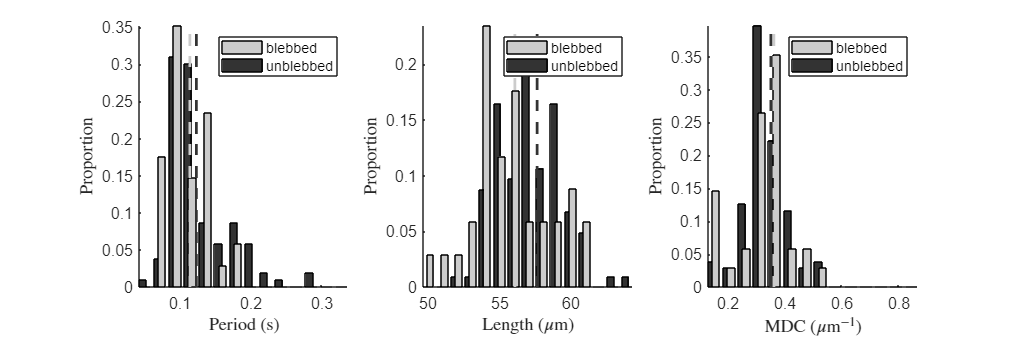

xlabel('MDC ($\mu$m$^{-1}$)','interpreter',"latex")
ylabel('Proportion','interpreter',"latex")
set(gca,'FontSize',axlabels_FontSize)
axis tight